# **Group assignment – Modeling Biosystems 2022: Fibroblast Encapsulation Model**

**Group 3: **

Sonia Bălan

Alex Rovira Rincon

Sebastian Ayala Ruano

Alaric de Biolley 

% Remove items from workspace
clear all; close all;

### Definition of parameters for the model

param.R= 0.001; %debris removal rate
param.k0= 1; %M0 migration rate
param.Mmax= 10; %maximal M0
param.dM0= 0.1; %M0 apoptosis rate
param.vmax1= 0.1; %MM vmax rate M0 to M1
param.km1= 2; %MM km M0 to M1
param.dM1= 0.05; %M1 apoptosis rate
param.vmax2= 0.1; %MM vmax rate M0 to M2
param.km2= 1; %MM km M0 to M2
param.dM2= 0.01; %M2 apoptosis rate
param.kDc1= 0.01; %constant c1 production rate by debris
param.kM1= 0.1; %constant c1 production rate by M1
param.dc1= 0.5; %c1 removal rate
param.kM2= 0.1; %constant c2 production rate by M2
param.dc2= 0.5; %c2 removal rate 
param.kf= 0.01; %proliferation rate F
param.Fmax= 2; %maximal F
param.df= 0.2; %F apoptosis rate

### **SECTION 1: ODEs **

### 3) Hill-type parameter estimation

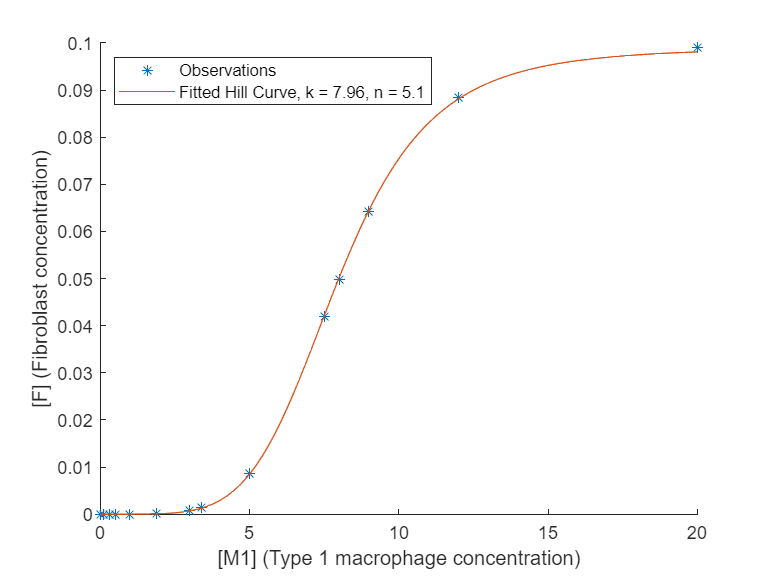

M1_obs = [0; 0.1; 0.3; 0.5;1; 1.9; 3; 3.4; 5; 7.5; 8; 9; 12; 20];
F_obs = [0; 3.04E-11; 7.45E-09; 9.54E-08; 3.01E-06; 7.55E-05; 0.000738; 0.001362; 0.008706; 0.042005; 0.0499; 0.064312; 0.088364; 0.098986];
param.FMM = max(F_obs); % maximum fibroblast migration rate
hn = 1:0.1:10;
hk = 0.1:0.01:max(M1_obs); 

for i = 1:length(hn)
    for j = 1 :length(hk)
        hill = hill_eq(hk(j),hn(i),M1_obs,param.FMM);
        RMSE(i, j) = sqrt(mean((F_obs - hill).^2));
    end
end

min_RMSE = min(RMSE,[],'all');
[x,y] = find(RMSE==min_RMSE);
param.hk = hk(y); %hill type parameter k (migration rate constant)
param.hn = hn(x); %hill type parameter n (power)

X = linspace(0,max(M1_obs));
hill_final = hill_eq(param.hk, param.hn,X,param.FMM);

figure;
hold on;
plot(M1_obs, F_obs,'*');
plot(X, hill_final);
xlabel('[M1] (Type 1 macrophage concentration)')
ylabel('[F] (Fibroblast concentration)')
hname = ['Fitted Hill Curve, k = ', num2str(param.hk), ', n = ',num2str(param.hn)];
legend('Observations',hname,'Location','Northwest');
hold off;

### 4) ODE Simulation

#### Set initial conditions

% Set the time of the simulation
t0 = 0; tf = 2000;  %(s)

% Set the initial conditions (nondimensional)
%         D; C1; C2; M0; M1; M2; F
x0_low = [10; 0.1; 0.1; 1; 0; 0; 0]; 
x0_high = [50; 0.1; 0.1; 1; 0; 0; 0]; 

#### Low initial concentration of debris simulation

% Solve the ODE system
[T_low,X_low] = ode15s(@fibroblastencaps,[t0 tf],x0_low,[],param);


#### Plot all the low initial concentrations together

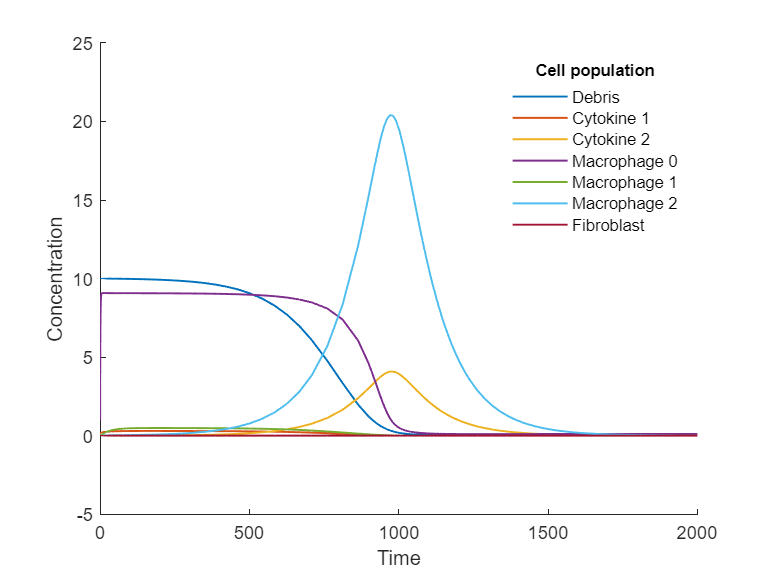

figure;
hold on
for i=1:length(x0_low)
    plot(T_low,X_low(:,i), 'LineWidth', 1.05);
end  
xlabel('Time');
ylabel('Concentration');
%title('Change in concentrations over time (initial debris concentration is low')
leg = legend('Debris', 'Cytokine 1', 'Cytokine 2','Macrophage 0','Macrophage 1','Macrophage 2','Fibroblast','Location','NorthEast');    
title(leg,'Cell population');
legend('boxoff');
hold off;

#### Plot low initial individual concentrations

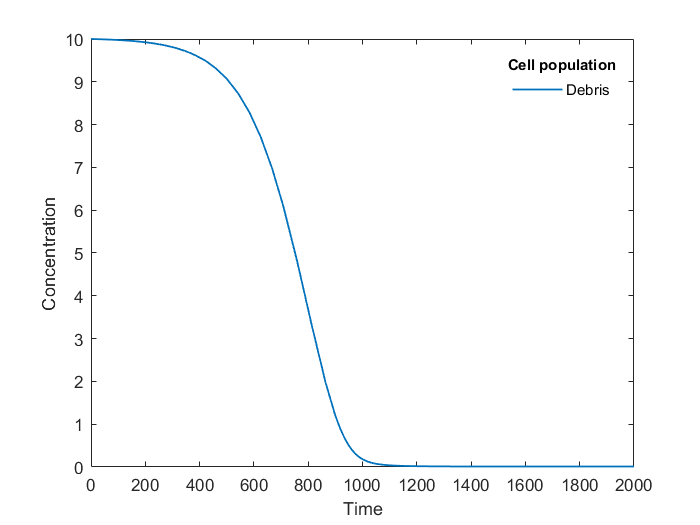

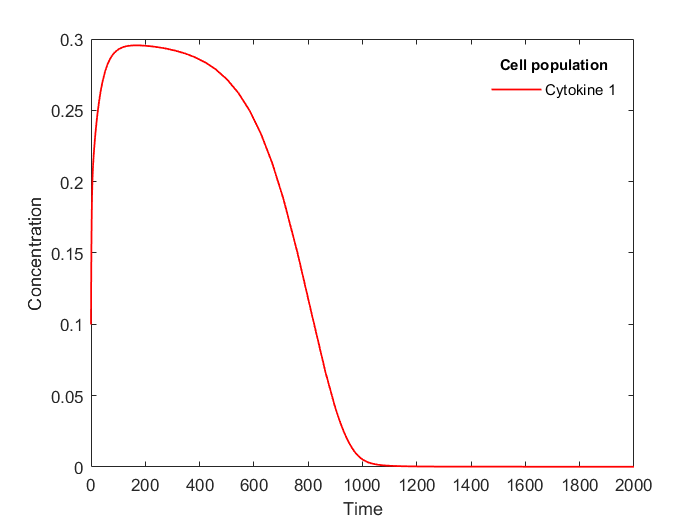

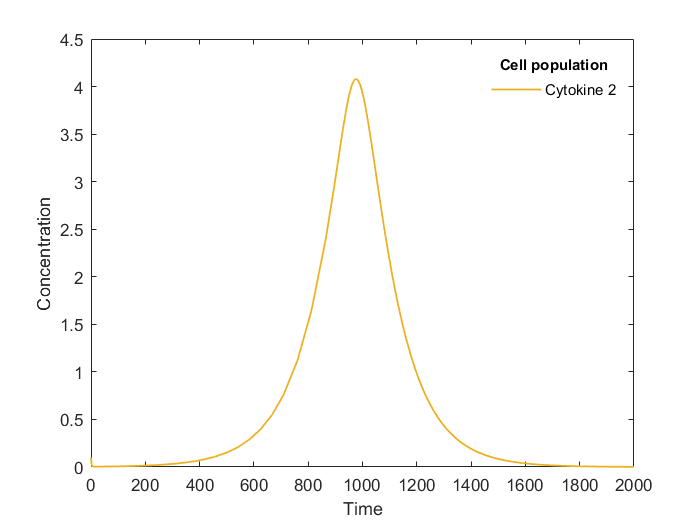

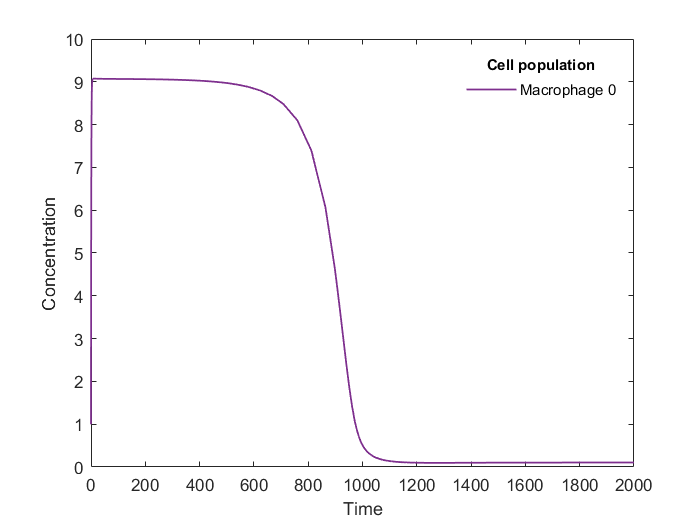

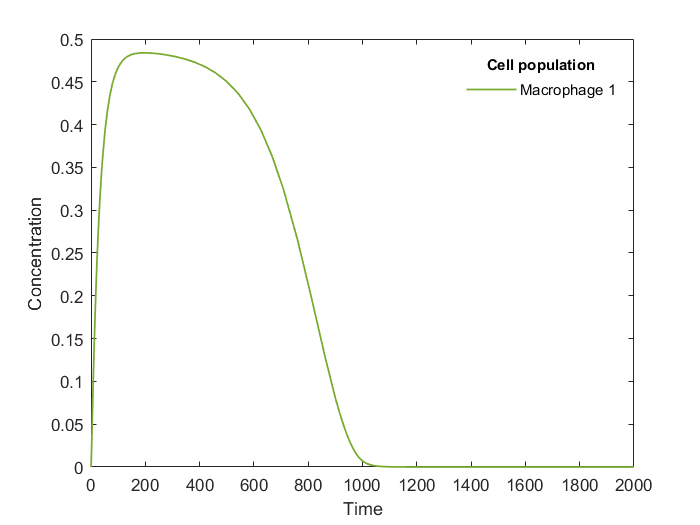

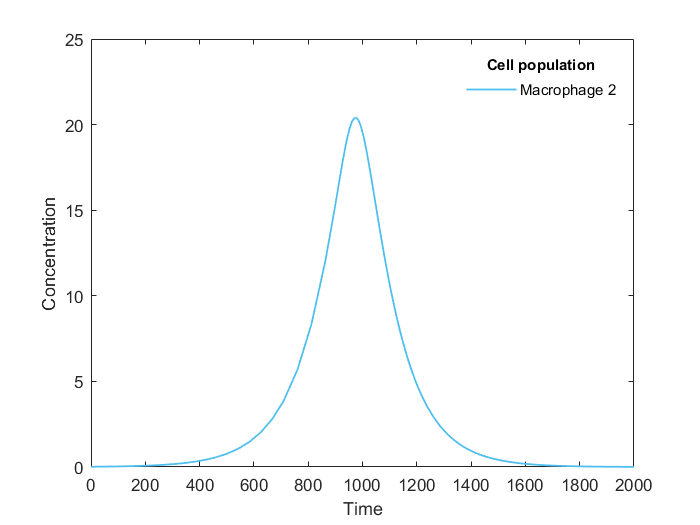

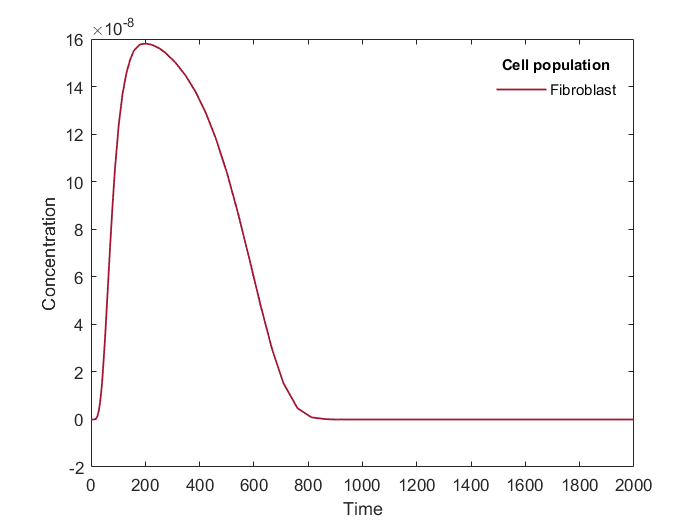

% Individual Concentrations
names = {['Debris'], ['Cytokine 1'], ['Cytokine 2'], ['Macrophage 0'], ['Macrophage 1'], ['Macrophage 2'], ['Fibroblast'], 'Drug1', 'Drug2'};
options = {[0 0.4470 0.7410], [1 0 0], [0.9290 0.6940 0.1250], [0.4940 0.1840 0.5560], [0.4660 0.6740 0.1880], [0.3010 0.7450 0.9330], [0.6350 0.0780 0.1840], [1 1 1], [1 1 1]};
for i=1:length(x0_low)
    if i <= 7
        figure
        plot(T_low,X_low(:,i),'Color', options{i}, 'LineWidth', 1.05);
        xlabel('Time');
        ylabel('Concentration');
        leg = legend(names(i),'Location','NorthEast');
        title(leg,'Cell population');
        legend('boxoff');
    end
end  

#### High initial concentration of debris simulation

% Solve the ODE system
[T_high,X_high] = ode15s(@fibroblastencaps,[t0 tf],x0_high,[],param);

#### Plot all the high initial concentrations together

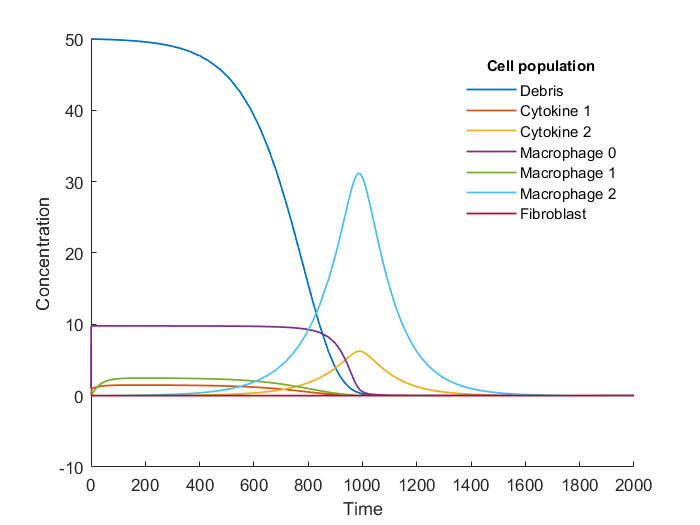

figure;
hold on
for i=1:length(x0_high)
    plot(T_high,X_high(:,i), 'LineWidth', 1.05);
end  
xlabel('Time');
ylabel('Concentration');
%title('Change in concentrations over time (initial debris concentration is high')
leg = legend('Debris', 'Cytokine 1', 'Cytokine 2','Macrophage 0','Macrophage 1','Macrophage 2','Fibroblast','Location','NorthEast');    
title(leg,'Cell population');  
legend('boxoff');
hold off;

#### Plot high initial individual concentrations

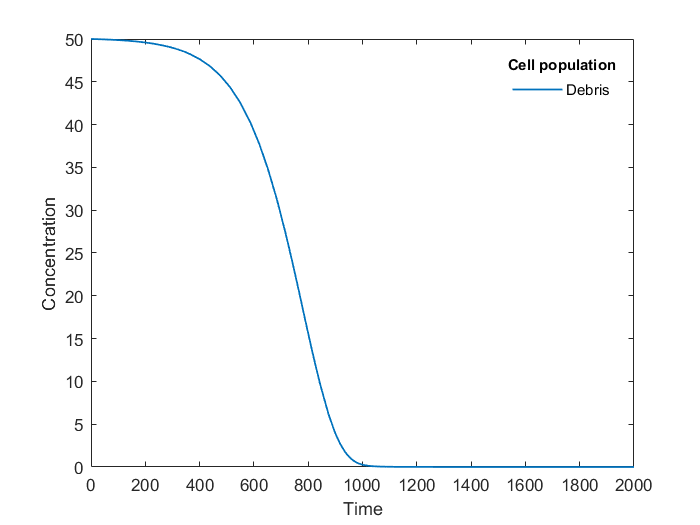

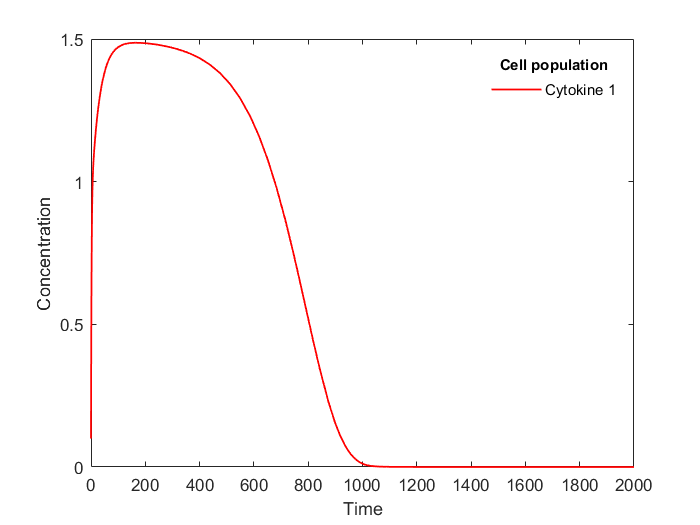

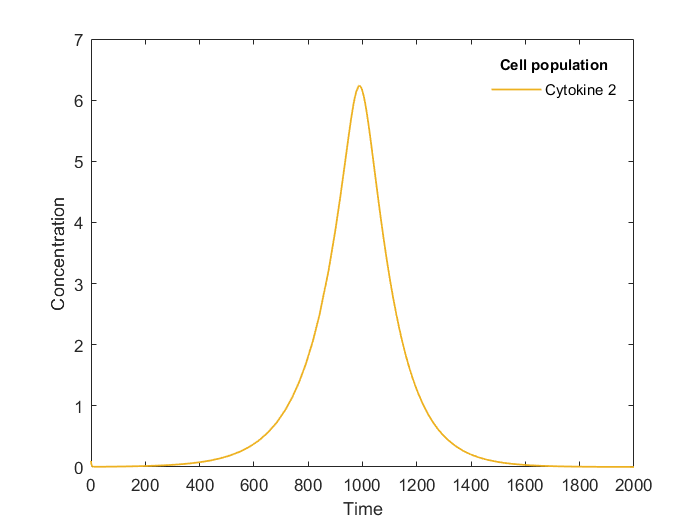

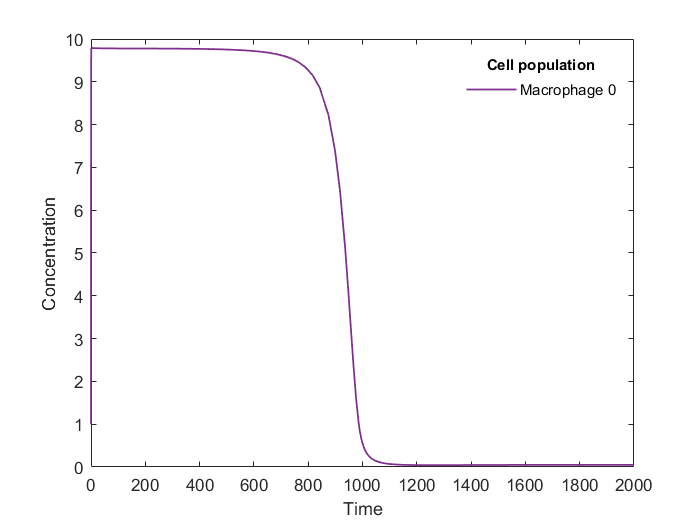

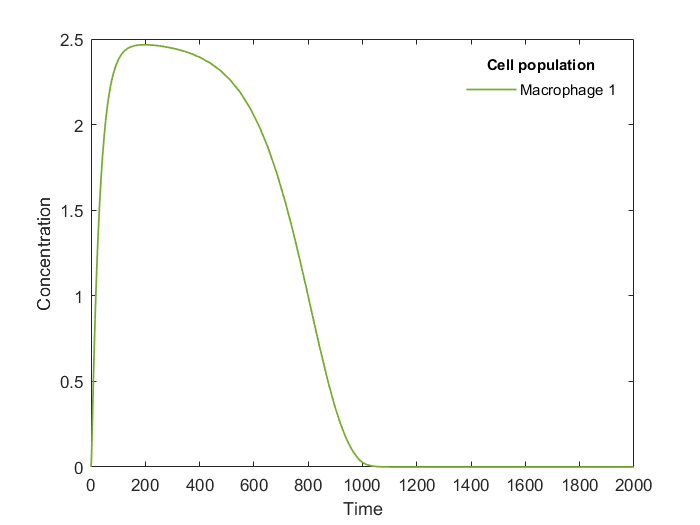

% Individual Concentrations
names = {['Debris'], ['Cytokine 1'], ['Cytokine 2'], ['Macrophage 0'], ['Macrophage 1'], ['Macrophage 2'], ['Fibroblast'], 'Drug1', 'Drug2'};
options = {[0 0.4470 0.7410], [1 0 0], [0.9290 0.6940 0.1250], [0.4940 0.1840 0.5560], [0.4660 0.6740 0.1880], [0.3010 0.7450 0.9330], [0.6350 0.0780 0.1840], [1 1 1], [1 1 1]};
for i=1:length(x0_high)-2
    figure
    plot(T_high,X_high(:,i),'Color', options{i}, 'LineWidth', 1.05);
    xlabel('Time');
    ylabel('Concentration');
    leg = legend(names(i),'Location','NorthEast');
    title(leg,'Cell population');   
    legend('boxoff');
end

### 5) Anti-inflammatory drug treatment

#### Set initial conditions 

% antiinflammatory drug treatment option
param.drug1 = 0.1; %arbitrary rates
param.drug2 = 0.1; 
param.kdrug1 = 0.01; %k for log growth; 
param.kdrug2 = 0.01; %k for log growth; 
param.dDrug1 = 0.0005; % drug1 clearance rate;
param.dDrug2 = 0.0005;% drug2 clearance rate; assumption: all molecules (like c1 and c2) are removed at the same rate

% Set the initial conditions (nondimensional)
%         D; C1; C2; M0; M1; M2; F; drug1; drug2
x0_low_drug = [10; 0.1; 0.1; 1; 0; 0; 0; 0.2; 0.2]; 
x0_high_drug = [50; 0.1; 0.1; 1; 0; 0; 0; 0.2; 0.2]; 

#### Drug treatment 1 simulation

param.TreatmentOption = 1;
[T_drug1,X_drug1] = ode15s(@fibroblastencaps_drug,[t0 tf],x0_low_drug,[],param);


#### Drug treatment 2 simulation

param.TreatmentOption =2;
[T_drug2,X_drug2] = ode15s(@fibroblastencaps_drug,[t0 tf],x0_low_drug,[],param);


#### Drug treatment 3 simulation

param.TreatmentOption =3;
[T_bothdrugs,X_bothdrugs] = ode15s(@fibroblastencaps_drug,[t0 tf],x0_low_drug,[],param);


#### Plot of the concentrations with the drug treatments

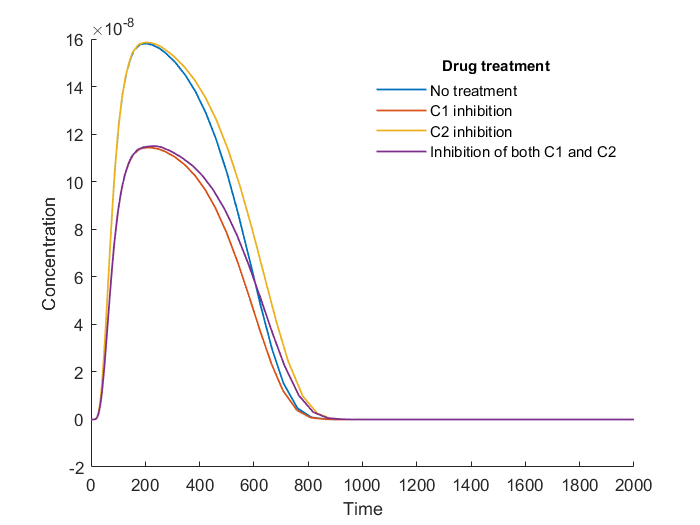

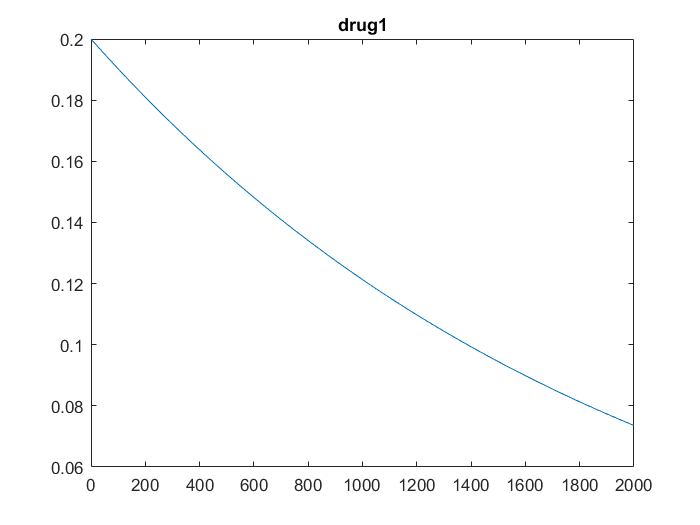

figure
hold on;
plot(T_low,X_low(:,7), 'LineWidth', 1.05);
plot(T_drug1,X_drug1(:,7), 'LineWidth', 1.05);
plot(T_drug2,X_drug2(:,7), 'LineWidth', 1.05);
plot(T_bothdrugs,X_bothdrugs(:,7), 'LineWidth', 1.05);
xlabel('Time');
ylabel('Concentration');
leg = legend('No treatment','C1 inhibition','C2 inhibition','Inhibition of both C1 and C2', 'Location','NorthEast');
title(leg,'Drug treatment'); 
legend('boxoff');
hold off;

### Supporting functions

function dx=fibroblastencaps(t,x,param)
    % Assign parameters for the simulation 
    D = x(1);
    C1 = x(2);
    C2 = x(3);
    M0 = x(4);
    M1 = x(5);
    M2 = x(6);
    F = x(7);

    % Define equations for the simulation
    % Debris cell pupulation with law of mass action
    dD = -param.R*M2*D; 
    % Michaelis-menten equation rate for transformation from M0 to M1
    m1 = mich_menten(param.vmax1, M0, param.km1);
    dM1 = C1*m1 - param.dM1*M1;
    % Michaelis-menten equation rate for transformation from M0 to M2
    m2 = mich_menten(param.vmax2, M0, param.km2);
    dM2 = C2*m2 - param.dM2*M2;
    % Logistic equation for Macrophages M0
    dM0 = logistic_eq(D, param.Mmax, param.k0, M0) - C1*m1 - C2*m2 - param.dM0*M0; 
    % Pro-inflammatory cytokines (C1) with law of mass action
    dC1 = param.kDc1*D + param.kM1*M1 - param.dc1*C1;
    % Anti-inflammatory cytokines (C2) with law of mass action
    dC2 = param.kM2*M2 - param.dc2*C2;
    % Fibroblast with the hill equation
    h = hill_eq(param.hk, param.hn, M1, param.FMM);
    dF = logistic_eq(param.kf, param.Fmax, F, F) + h*M1 - param.df*F;
    
    % Return the equations
    dx = [dD; dC1; dC2; dM0; dM1; dM2; dF];
end

function dx = fibroblastencaps_drug(t,x,param)
    D = x(1);
    C1 = x(2);
    C2 = x(3);
    M0 = x(4);
    M1 = x(5);
    M2 = x(6);
    F = x(7);
    drug1 = x(8);
    drug2 = x(9);
    
    % setting drug effect parameters based on treatment option
    param.Kdrug1 = 0; % effect of drug 1 on C1
    param.Kdrug2 = 0; % effect of drug 2 on C2
    if param.TreatmentOption == 1
        param.Kdrug1 = param.drug1; 
    elseif param.TreatmentOption == 2
        param.Kdrug2 = param.drug2;
    elseif param.TreatmentOption == 3
        param.Kdrug1 = param.drug1;
        param.Kdrug2 = param.drug2;
    end
    
    % either increase removal or decrease influence on michaelis menten rates for M1 and M2
    
    ddrug1 =  - param.dDrug1*drug1; %logistic - removal rate
    ddrug2 =  - param.dDrug2*drug2; %logistic - removal rate
    
    % Define equations for the simulation
    % Debris cell pupulation with law of mass action
    dD = -param.R*M2*D; 
    % Michaelis-menten equation rate for transformation from M0 to M1
    m1 = mich_menten(param.vmax1, M0, param.km1);
    dM1 = C1*m1 - param.dM1*M1;
    % Michaelis-menten equation rate for transformation from M0 to M2
    m2 = mich_menten(param.vmax2, M0, param.km2);
    dM2 = C2*m2 - param.dM2*M2;
    % Logistic equation for Macrophages M0
    dM0 = logistic_eq(D, param.Mmax, param.k0, M0) - C1*m1 - C2*m2 - param.dM0*M0; 
    % Pro-inflammatory cytokines (C1) with law of mass action and modified with the drug treatment 
    dC1 = param.kDc1*D + param.kM1*M1 - param.dc1*C1 - param.Kdrug1*drug2*C1;
    % Anti-inflammatory cytokines (C2) with law of mass action and modified with the drug treatment
    dC2 = param.kM2*M2 - param.dc2*C2 - param.Kdrug2*drug2*C2;
    % Fibroblast with the hill equation
    h = hill_eq(param.hk, param.hn, M1, param.FMM);
    dF = logistic_eq(param.kf, param.Fmax, F, F) + h*M1 - param.df*F;
    
    % Return the equations
    dx = [dD; dC1; dC2; dM0; dM1; dM2; dF; ddrug1; ddrug2];
end


function c =hill_eq(k,n,C,MR) % hill type function
% INPUTS: 
    % k - rate constant
    % n - power 
    % C - independent concentration
    % MR - maximum rate
    c = MR*C.^n./(k^n + C.^n);
end

function m = mich_menten(vmax, concent, km)
% INPUTS: 
    % vmax - maximum rate
    % concent - substrate concentration
    % km - MM constant
    m = (vmax*concent)/(km + concent);
end

function l = logistic_eq(r, K, pop1, pop2)
% INPUTS: 
    % r - growth rate
    % K - carrying capacity 
    % pop1 - population 1
    % pop1 - population 2
    l = r*pop1*(1 -(pop2/K)); 
end